# Pop vs. Area Model NEW

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')

## Pop vs. Area

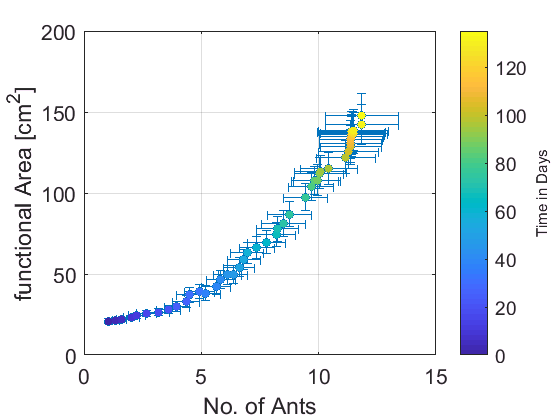

t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);
A = M(1).Mean(t0:tend);
Aer = M(1).SEM(t0:tend);
N = M(13).Mean(t0:tend);
Ner = M(13).SEM(t0:tend);

figure
errorbar(N,A,Aer,Aer,Ner,Ner,'o')
hold on
scatter(N,A,[],t1,'filled')
xlabel('No. of Ants')
ylabel('functional Area [cm^2]')
grid on
c = colorbar;
c.Label.String = 'Time in Days'; c.Label.FontSize = 11;

%title('Mean fArea vs. Mean Population (error bars = SEM)- interpolated for missing values ')


## Linear fit from 5 workers

More5idx = find(N>=5);
N5 = N(More5idx);
A5 = A(More5idx);
t5 = t1(More5idx);
figure
scatter(N5,A5,[],t5)

lm = fitlm(N5,A5)

lm = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________
    (Intercept)    -52.287      2.9077    -17.982    2.7343e-18
    x1              16.253     0.30443     53.387    7.4996e-33

Number of observations: 34, Error degrees of freedom: 32
Root Mean Squared Error: 3.77
R-squared: 0.989,  Adjusted R-Squared 0.989
F-statistic vs. constant model: 2.85e+03, p-value = 7.5e-33

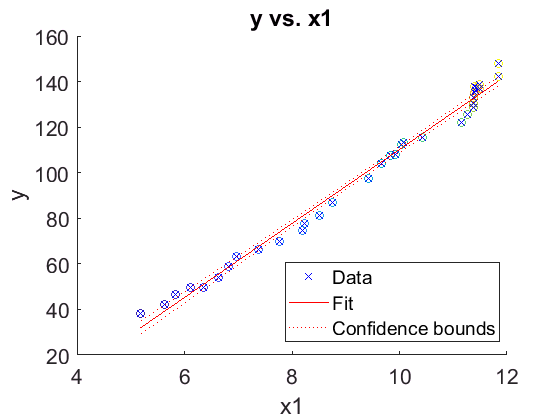

hold on
plot(lm)



sA5 = A5./N5;
MinimalSA = min(sA5)

MinimalSA = 7.3764

MaximalSA = max(sA5)

MaximalSA = 12.5104

MeanSA = mean(sA5)

MeanSA = 10.2909

SD_SA = std(sA5)

SD_SA = 1.5703

**Density model**

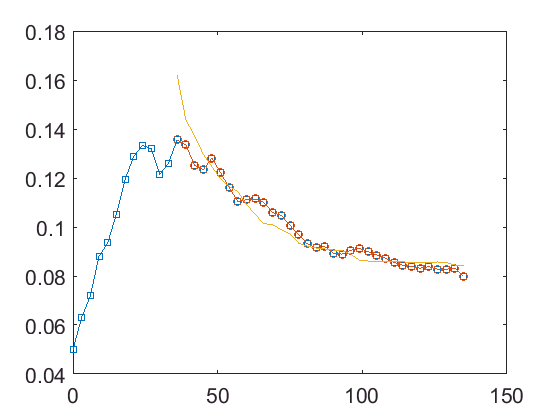

d = N./A;
d5pred = N5./predict(lm,N5);
figure; plot(t1,d,'-s',t5,sA5,'-o',t5,d5pred)

reorganize to get 'y=ax' fit

N5i = N5-repmat(5,numel(N5),1);
A5i = A5-repmat(A5(1),numel(A5),1);

lm2 = fitlm(N5i,A5i,'y~x1-1')

lm2 = Linear regression model:
    y ~ x1

Estimated Coefficients:
          Estimate      SE       tStat       pValue  
          ________    _______    ______    __________
    x1    14.519      0.19905    72.944    4.7127e-38

Number of observations: 34, Error degrees of freedom: 33
Root Mean Squared Error: 5.58

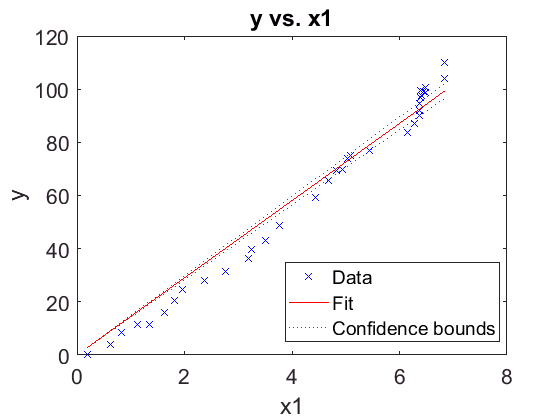

figure; plot(lm2)

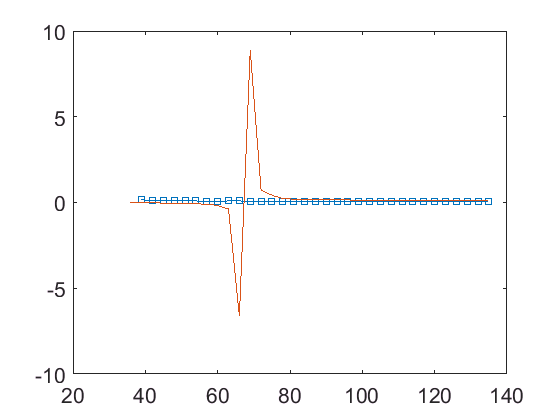


d = N5i./A5i;
d5pred = N5i./predict(lm,N5i);
figure; plot(t5,d,'-s',t5,d5pred)

## Look at % deviation from optimal density

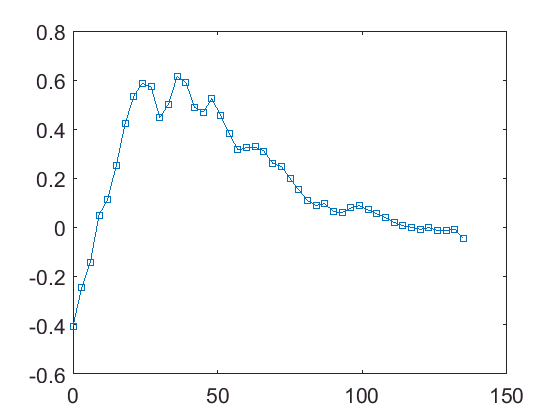

optD = 0.084;
D=N./A;
dev = (D-repmat(optD,numel(D),1))./optD;
figure
plot(t1,dev,'-s')

## Check corr and x-corr between dAdt and density

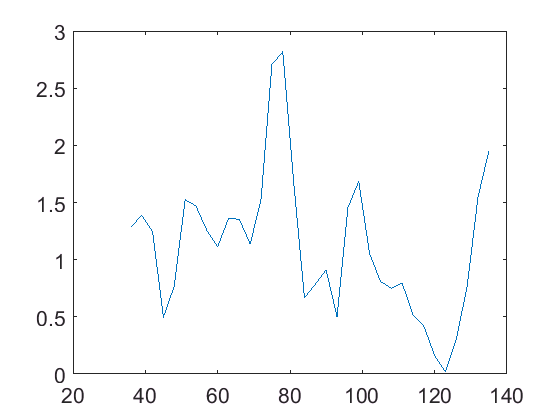

dAdt =gradient(A5)./3;
D = N5./A5;
figure; plot(t5,dAdt)

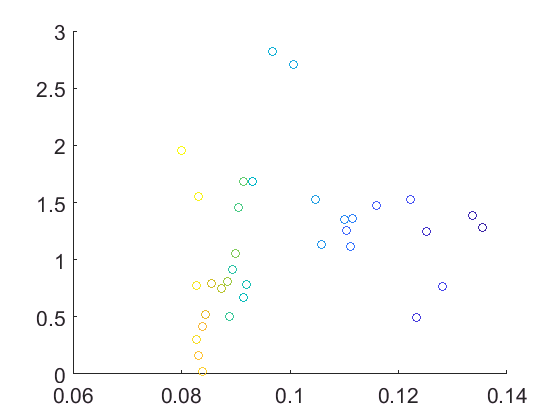

figure;
scatter(D,dAdt,[],t5)

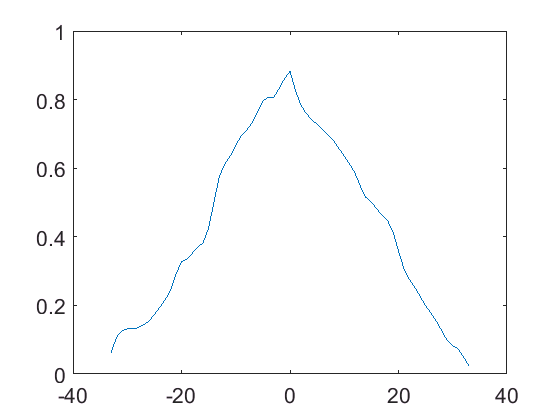


[r,lags]=xcorr(D,dAdt,'coeff');
figure; plot(lags,r)

Conclusion

X-corr: past density is positively correlated w/ present digging rate

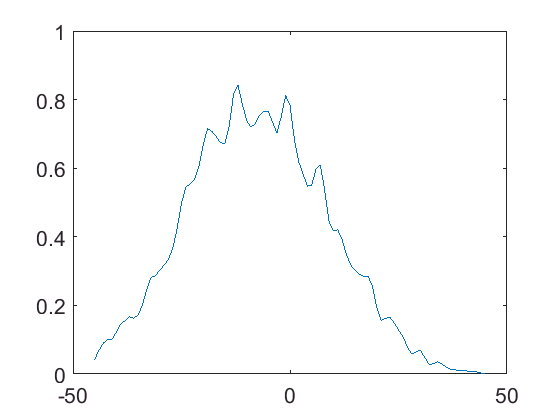

dNdt = gradient(N)./3;
dAdt = gradient(A)./3;
[r,lags]=xcorr(dNdt,dAdt,'coeff');
figure; plot(lags,r)

## Plot 3 specific experiments (F3,F25,F29) pop vs. area plots

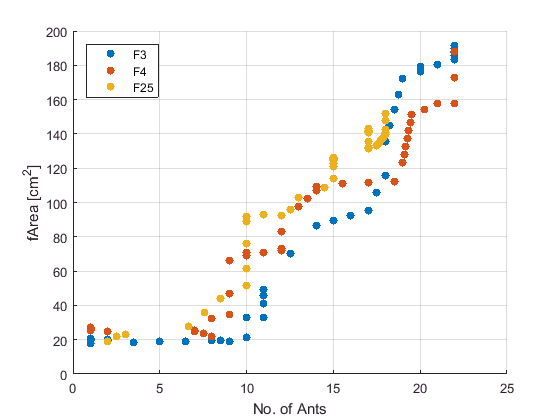

figure
for k=[3 4 25]
    hold on
    fA = S(k).B.fArea(t0:tend);
    N = S(k).B.SmoothPop(t0:tend);
    scatter(N,fA,'filled')
end
grid on
xlabel('No. of Ants')
ylabel('fArea [cm^2]')
legend({'F3','F4','F25'},'Location','northwest')

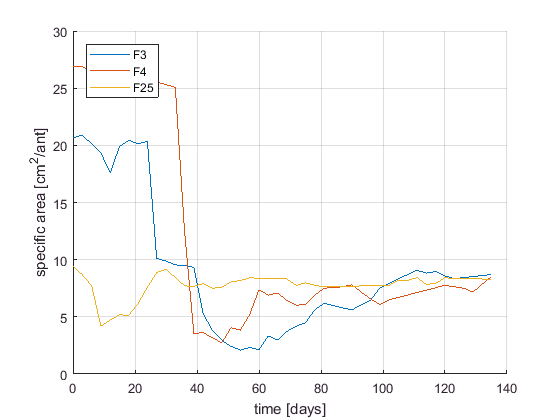


figure
for k=[3 4 25]
    hold on
    fA = S(k).B.fArea(t0:tend);
    N = S(k).B.SmoothPop(t0:tend);
    sA = fA./N;
    plot(t1,sA)
end
grid on
xlabel('time [days]')
ylabel('specific area [cm^2/ant]')
legend({'F3','F4','F25'},'Location','northwest')